    % System Pressures
P5 = 6.8e3; % [Pa]
P2 = 170e5; % [Pa]
P3 = 0.92*P2; % Pressures assuming 8% drop over each component
P4 = 0.92*P3; % [Pa]
P1 = P2/0.92; % [Pa]
P6 = 0.92*P5; % [Pa]
P8 = 10e5; % [Pa]
P7 = P8/0.92; % [Pa]

w = Water; % used for various calculations
X_5 = 0.85; % Quality of steam leving turbine

% Polytropic Efficiencies
eta_pump = 0.85;
eta_turb = 0.8;

% Find corresponding turbine input temp (T4)
T4 = 797.3; % guess and check for turbine output with 0.85 vapor quality
set(w, "T", T4, "P", P4)
s4 = entropy_mass(w);
h4 = enthalpy_mass(w);
[turb_w, h_out, X_turb_out] = turb_work(eta_turb, P4, P5, h4);
h5 = h4 + turb_w;
set(w, "P", P5, "H", h5);
T5 = temperature(w);
s5 = entropy_mass(w);

% Condenser
set(w, "P", P6);
setState_satLiquid(w);
T6 = temperature(w);
s6 = entropy_mass(w);
h6 = enthalpy_mass(w);
q_out = h6-h5;

% Pump 2 
[pump2_w, h_out] = pump_work(eta_pump, P6, P7, h6);
h7 = h6 + pump2_w;
set(w, "H", h7, "P", P7)
T7 = temperature(w);
s7 = entropy_mass(w);

% State 8
T8 = 453.099; % Found experimentally as sat liquid @ 10 bar

% Mixing in Aerorator
% (1-m)*enthalpy(S7) + m*enthalpy(S5) = enthalpy(S8)
% m*( enthalpy(S5)-enthalpy(S7) ) = enthalpy(S8) - enthalpy(S7)
% m = (enthalpy(S8) - enthalpy(S7)) / (enthalpy(S5)-enthalpy(S7))
set(w, "T", T8, "P", P8);
h8 = enthalpy_mass(w);
s8 = entropy_mass(w);
m = (h8-h7) / (h5-h7); % Fraction of steam leached from turbine to aerorator

% Pump 1
[pump1_w, h_out] = pump_work(eta_pump, P8, P1, h8);
h1 = h8+pump1_w;
set(w, "H", h1, "P", P1)
T1 = temperature(w);
s1 = entropy_mass(w);

setState_Psat(w, [P2, 0])
h2 = enthalpy_mass(w);
s2 = entropy_mass(w);
T2 = temperature(w);

setState_Psat(w, [P3, 1])
pressure(w)

ans = 1.5640e+07

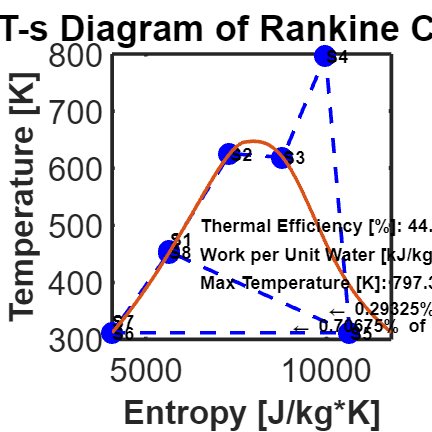

h3 = enthalpy_mass(w);
s3 = entropy_mass(w);
T3 = temperature(w);

q_in = h4 - h1; % lump economizer, vaporator, superheater

% System Metrics
net_work = pump1_w + pump2_w + turb_w;

eta_cycle = abs(net_work/q_in);
eta_ideal = (T4-T6)/T4;
eta_2nd_law = eta_cycle/eta_ideal;

enthalpies = [h1 h2 h3 h4 h5 h6 h7 h8 h5];
temps = [T1 T2 T3 T4 T5 T6 T7 T8 T5];
entropies = [s1 s2 s3 s4 s5 s6 s7 s8 s5];
plot(entropies, temps, "--ob")
title("T-s Diagram of Rankine Cycle")
ylabel("Temperature [K]")
xlabel("Entropy [J/kg*K]")

% Label States
for i = 1:size(temps,2)-1
    if i == 1 || i == 7
        h = 20;
    else
        h = 0;
    end
    text(entropies(i),temps(i)+h,strcat("S",int2str(i)), "FontWeight", "bold")
end

% Generate Vapor Dome
i = 1;
T_crit = critTemperature(w);
P_crit = critPressure(w);
for t = min(temps):1:T_crit-1
    set(w, "T", t, "Liquid", 1)
    T_dome(i) = temperature(w);
    S_dome(i) = entropy_mass(w);
    i = i + 1;
end

set(w, "T", T_crit, "P", P_crit)
T_dome(i) = temperature(w);
S_dome(i) = entropy_mass(w);
i = i + 1;

for t = T_crit-1:-1:min(temps)
    set(w, "T", t, "Vapor", 1)
    T_dome(i) = temperature(w);
    S_dome(i) = entropy_mass(w);
    i = i + 1;
end

hold on
plot(S_dome, T_dome)
hold off

% Add labels for thermal efficiency, work per unit water, max temp
text(6500,500,strcat("Thermal Efficiency [%]: ", num2str(eta_cycle*100)), "FontWeight", "bold")
text(6500,450,strcat("Work per Unit Water [kJ/kg]: ", num2str(-net_work/1e3)), "FontWeight", "bold")
text(6500,400,strcat("Max Temperature [K]: ", num2str(T4)), "FontWeight", "bold")
text(10000, 350, strcat("\leftarrow ",num2str(m),"% of flow"), "FontWeight", "bold")
text(9000, 320, strcat("\leftarrow ",num2str(1-m),"% of flow"), "FontWeight", "bold")

improvePlot

function [total_w, H, X] = turb_work(eta, Pin, Pout, h0)
    w = Water;
    set(w, "H", h0, "P", Pin) % Initial Conditions of water
    n = 100; % discretization points for pressure
    h = (Pout-Pin)/n; % integration step
    total_w = 0; % total work output of turbine
    for p = Pin+h:h:Pout
        h1 = enthalpy_mass(w);
        s0 = entropy_mass(w);
        setState_SP(w, [s0, p]) % isentropic expansion
        h2 = enthalpy_mass(w);
        dw_s = h2-h1; % isentropic work
    
        dw = dw_s*eta; % actual work
        setState_HP(w, [h1+dw, p]) % actual new state of steam 
        total_w = total_w + dw; % sum all steps
    end
    X = vaporFraction(w);
    H = enthalpy_mass(w);
end

function [total_w, H] = pump_work(eta, Pin, Pout, h0)
    w = Water;
    set(w, "H", h0, "P", Pin) % Initial Conditions of water
    n = 100; % discretization points for pressure
    h = (Pout-Pin)/n; % integration step
    total_w = 0; % total work output of turbine
    for p = Pin+h:h:Pout
        h1 = enthalpy_mass(w);
        s0 = entropy_mass(w);
        setState_SP(w, [s0, p]) % isentropic expansion
        h2 = enthalpy_mass(w);
        dw_s = h2-h1; % isentropic work
    
        dw = dw_s/eta; % actual work
        setState_HP(w, [h1+dw, p]) % actual new state of steam 
        total_w = total_w + dw; % sum all steps
    end
    H = enthalpy_mass(w);
end